## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from PDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## fv01 Intro

we want to plot curves with different para.

## Import data and previewing

The data come from expomential fitness data.

experiment_interval=1;
min_length=100;
time_scale=experiment_interval*(1:min_length);
kB=1.3806505e-23;
T=293;%confirmed

## Parameter importing

range_mpsi=5e-8;%1e-8:9e-8;%m
range_zeta=1e-7;%*[0.5,2,5,10,20];
range_H=[0.55,0.65,0.75,0.8,0.85];
figure

## Main loop

for mpsi=range_mpsi
    for zeta=range_zeta
        for H=range_H
            simulation_MSD=[];
            tau=((zeta*gamma(2*H+1))/mpsi)^(1/(2-2*H));
            for t=experiment_interval*[1:min_length]
                simulation_MSD=[simulation_MSD,2*kB*T/mpsi-2*kB*T/mpsi*mlf(2-2*H,1,-(t/tau)^(2-2*H),8)];
            end
            legend_name=strcat(' m\psi= ',num2str(mpsi),'m \zeta=',num2str(zeta),' H= ',num2str(H));
            plot(time_scale,simulation_MSD,'DisplayName',legend_name,'LineWidth',2);
            hold on
        end
    end
end


## Plot and saving

xlabel('t  /  s','FontSize',15);
ylabel('MSD / m^2','FontSize',15);
title('changing H','FontSize',20);
legend('Location','best');

## Saving

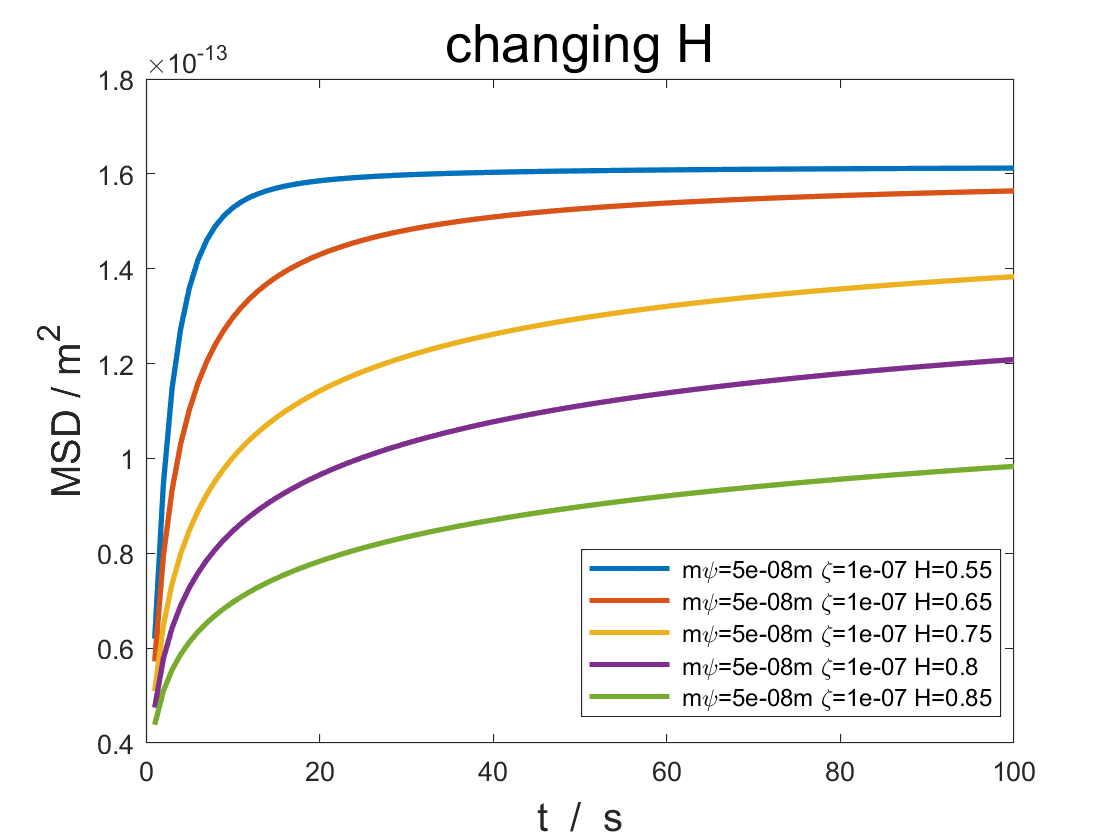

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.04图像';
saveas(gcf,strrep([storage_location,'\image\GKENII-MSD','.mpsi=',num2str(mpsi),'.zeta=',num2str(zeta),'.H=',num2str(H),'.jpg'],'       ',' '))